# Pdf and Cdf of Weibull RV

Note: this script reproduces the figure of the Weibull RV in Section 2.2.7 of **Statistics for Chemical Engineers**. Victor Z UW-Madison, 2019 compare weibull RVs

clc; clear all; close all hidden;

## Parameters

define parameters

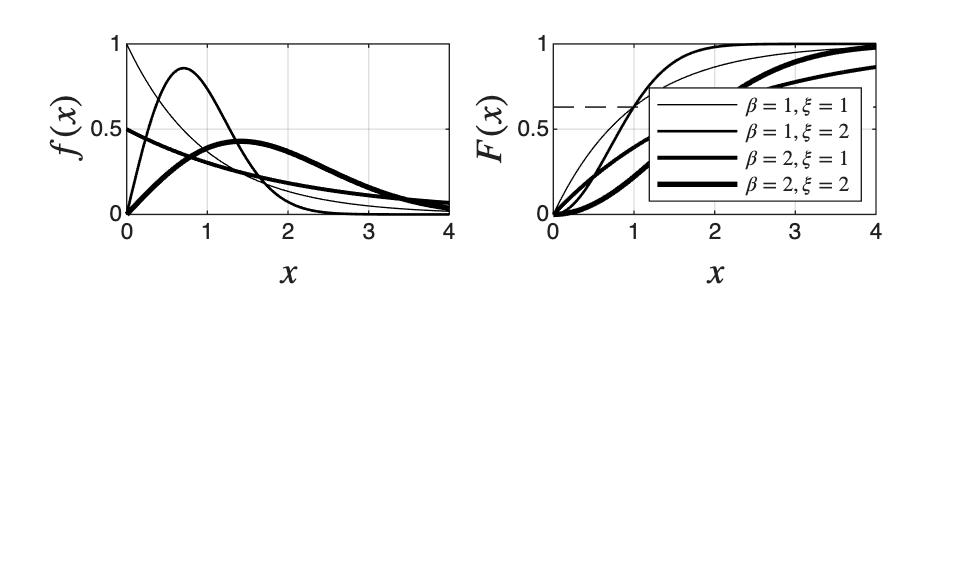

 beta=[1,1,2,2];
   xi=[1,2,1,2];
w=[0.5,1,1.5,2];
x=linspace(0,4,1000);
n=length(x);

subplot(2,2,1)
for k=1:length(beta)
plot(x,wblpdf(x,beta(k),xi(k)),'black','LineWidth',w(k))
hold on
end
grid on
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
title('')

subplot(2,2,2)
for k=1:length(beta)
plot(x,wblcdf(x,beta(k),xi(k)),'black','LineWidth',w(k))
hold on
end
grid on
plot(x,ones(n,1)*0.63,'black--')
lgd=legend('$\beta=1,\xi=1$','$\beta=1,\xi=2$','$\beta=2,\xi=1$','$\beta=2,\xi=2$','Interpreter','latex','location','southeast');
lgd.FontSize = 8;
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$F(x)$','Interpreter','latex','FontSize',14)
title('')
print -depsc ch2_compareweibull.eps

## Note

The shape parameter xi changes the form of the Weibull pdf; xi = 1 gives the exponential RV.